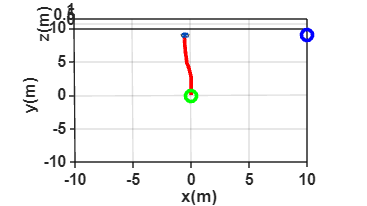

    %Limpieza de pantalla
clear all
close all
clc

%1 TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tf=15;             % Tiempo de simulación en segundos (s)
ts=0.1;            % Tiempo de muestreo en segundos (s)
t=0:ts:tf;         % Vector de tiempo
N= length(t);      % Muestras


%2 CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestro punto inicial de posición y orientación
x1(1)=0;  %Posición inicial eje x
y1(1)=0;  %Posición inicial eje y
phi(1)=pi/2; %Orientación inicial del robot 

%3 POSICION DESEADA %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Damos valores a nuestra posición deseada
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
hxd= 10;
hyd= 9;

%Igualamos el punto de control con las proyecciones X1 y Y1 por su
%coincidencia
hx(1)= x1(1);       % Posición del punto de control en el eje (X) metros (m)
hy(1)= y1(1);       % Posición del punto de control en el eje (Y) metros (m)

%4 CONTROL, BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 

    %a)Errores de control
    hxe(k)=hxd-hx(k);
    hye(k)=hyd-hy(k);
    
    %Matriz de error
    he= [hxe(k);hye(k)]; %tiene la forma 2*1  hxe y hye
    %Magnitud del error de posición
    Error(k)= sqrt(hxe(k)^2 +hye(k)^2);

    %b)Matriz Jacobiana
    J=[cos(phi(k)) -sin(phi(k));... %Matriz de rotación en 2D
       sin(phi(k)) cos(phi(k))];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %c)Matriz de Ganancias  %%%%%%%%%%%%%es la parte que debo de cambiar.
    K=[3 0;...
       0 3];

    %d)Ley de Control
    qpRef= pinv(J)*K*he;

    v(k)= qpRef(1);   %Velocidad lineal de entrada al robot 
    w(k)= qpRef(2);   %Velocidad angular de entrada al robot 


%5 APLICACIÓN DE CONTROL AL ROBOT %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %Aplico la integral a la velocidad angular para obtener el angulo "phi" de la orientación
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
           
   %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=v(k)*cos(phi(k)); 
    yp1=v(k)*sin(phi(k));
 
    %Aplico la integral a la velocidad lineal para obtener las cordenadas
    %"x1" y "y1" de la posición
    x1(k+1)=x1(k)+ xp1*ts; % Integral numérica (método de Euler)
    y1(k+1)=y1(k)+ yp1*ts; % Integral numérica (método de Euler)

    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);
     

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Configurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([-0.1 35]); % Orientacion de la figura
axis([-10 10 -10 10 0 1]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);
H3=plot3(hxd,hyd,0,'bo','lineWidth',2); %Grafico circulo en posición deseada
H4=plot3(hx(1),hy(1),0,'go','lineWidth',2);%Grafico circulo en posición inicial
% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

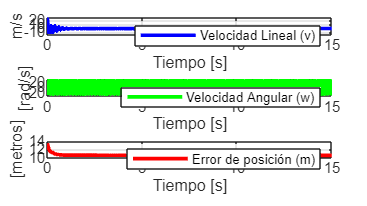


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(311)
plot(t,v,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('Velocidad Lineal (v)');
subplot(312)
plot(t,w,'g','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('Velocidad Angular (w)');
subplot(313)
plot(t,Error,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[metros]'),legend('Error de posición (m)');